addpath(genpath(pwd))
addpath(genpath('Z:\01_Codes_Projects\Torino_syRe'))

JMAG에서 특정 kW에 대해서 Q값 구하기

해당 d^2L 값 

전류밀도

온도

# Stipetic 코드화 

- Syre와 mcb 코드 최대한 활용하기

### 레퍼런스 값들

값 가져오기

- MotorCAD

- mcb (JMAG)

- JMAG Express (SingleValue)

 mcad=actxserver('motorcad.appautomation');

## Reference 데이터 가져오기

### MotorCAD

SatuMapFilePath='Z:\Thesis\HDEV\02_MotorCAD\MOT\12P72S_high_fidel_LAB_160point\Lab\SatuaMaptest.mat'
devExportSatuMapFromMCADLabModel(SatuMapFilePath,mcad)
load(SatuMapFilePath);

[~,RMSCurrent]=mcad.GetVariable('RMSCurrent')
[~,ParallelPaths]=mcad.GetVariable('ParallelPaths')
[~,NumberStrandsHand ]=mcad.GetVariable('NumberStrandsHand')
[~,ArmatureConductorCSA]=mcad.GetVariable('ArmatureConductorCSA')

RMSCurrentDensity =calcCurrentDensity(RMSCurrent,double(ParallelPaths),double(NumberStrandsHand),ArmatureConductorCSA)
someSlotArea= double(ParallelPaths)*ArmatureConductorCSA*double(NumberStrandsHand)
someSlotArea=RMSCurrent/RMSCurrentDensity
% someSlotArea=842.6/31.04  % RMS Current / RMS Current Density

% From devMBCTeslaSPlaidFromDankai
elecDataMatPath='Z:\01_Codes_Projects\git_fork_emach\tools\SystemSimulationModel\MotorLAB_elecdata.mat'
elecData=load(elecDataMatPath)
% SatuMapMatPath='Z:\01_Codes_Projects\git_fork_emach\tools\SystemSimulationModel\SatuMap.mat'
% SatuMapMatPath='Z:\Simulation\ACCESS2023\SaturationLossMap.mat'
% SatuMapData=load(SatuMapMatPath);

%%
% TeslaSPlaidGeometry=tempDefMCADMachineData4Scaling(mcad)
HDEVGeo=MotorCADGeo;

### syre

syreMatFilePath="Z:\01_Codes_Projects\Torino_syRe\motorExamples\TeslaModel3.mat"
load(syreMatFilePath)

## Scaling

% scaleMachine              % syRe : Geometry
% MMM_scale()
% MMM_eval_mapScale()
% devScaleMethodStiepetic   % stipetic 논문에서 수식 발췌 

#### Scale Coefficient

MotorCADGeo=TeslaSPlaidGeometry
Factor.k_Axial     =1.2;
Factor.k_Radial    =1.2;
% % k_Winding   =1;
Factor.n_c = 5
Factor.a_p = 3

n_c_ref = double(TeslaSPlaidGeometry.MagTurnsConductor); % turn per Coil
a_p_ref = double(TeslaSPlaidGeometry.ParallelPaths    ); % Parallel Path
Factor.k_Winding = (Factor.n_c/Factor.a_p)/(n_c_ref / a_p_ref)

#### 구조체 형태

% Scaled = devScaleMethodStiepetic(Factor,SatuMapData,TeslaSPlaidGeometry)

#### Table형태

[SatuMapTable,SatuMapInfo]=createTableFromMCADSatuMapStr(SatuMapData);
SatuMapTable.CurrentDensityRMS=SatuMapTable.Stator_Current_Line_RMS/someSlotArea
[ScaledMachineData,ScaledSatuMapTable] = devScaleTablebyStiepetic(Factor,SatuMapTable,TeslaSPlaidGeometry);


## DataFormat 변경 

#### [MotorCAD Lab Import용]  devSatuaMapTable2TXTinLabLinkFormat (열해석때문에)

%% Txt파일로 Export
devSatuaMapTable2TXTinLabLinkFormat(ScaledSatuMapTable)
%% Import in MotorCAD Lab
devImportExternalTXTSatuModel(LabLinkTxtPath,TeslaSPlaidGeometry,ScaledMachineData,SatuMapInfo,mcad)   

#### [syre]SatuMap 2 syre Format

MotorCADFEA=SatuMapData

motorModel=devConvertSatuMap2syreMotorModel(motorModel,MotorCADGeo,MotorCADFEA)
% MMM_plot_fdfq(motorModel2)
% MMM_eval_mapScale
% setup.lVect  = linspace(lMin,lMax,51);
% setup.NsVect = linspace(NsMin,NsMax,51);
Factor.k_Axial=1
Factor.k_Radial=0.5
kN=1
scaleFactors.Ns = kN *motorModel.data.Ns;
scaleFactors.l  = Factor.k_Axial *motorModel.data.l
scaleFactors.R  = Factor.k_Radial *motorModel.data.R
 % scaleFactors.Ns    =2
scaleFactors.Lld   =0
scaleFactors.Llq   =0

motorModel.controlTrajectories=[]
% motorModel.FluxMap_dqt=[]
% motorModel.dqtMap=[]
motorModel.FluxMapInv_dq=[]
motorModel.FluxMapInv_dqt=[]
motorModel.data.Imax=900
motorModel.data.nmax=5000

scaledModel=MMM_scale(motorModel,scaleFactors)
scaledModel.data.Imax=900
scaledModel.data.nmax=5000
b=motorModel.controlTrajectories.MTPA.id
a=scaledModel.controlTrajectories.MTPA.id
c=motorModel.controlTrajectories.MTPA.iq
d=scaledModel.controlTrajectories.MTPA.iq
plot(a)
hold on
plot(b)
plot(c)
hold on
plot(d)
% MMM_eval_AOA
scaledModel.controlTrajectories = MMM_eval_AOA(scaledModel,'LUT');
motorModel.controlTrajectories = MMM_eval_AOA(motorModel,'LUT');

close all
MMM_plot_fdfq(scaledModel)
MMM_plot_fdfq(motorModel)
% MMM_eval_mapScale(motorModel2)
MMM_eval_mapScale(scaledModel)
MMM_eval_mapScale(motorModel)

#### [TB]syreMMM2LabLink

## [TB] 특성 비교(TN 계산 !! -> 효율맵) 

방법론별

- Dankai 복습 -Gaussian Model -devMBCFromDankai.mlx 참조

- 테이블로 만들어서 Filter 걸기 (Physics 모델)

- SyRe 코드

% HDEV TN
Plim = cell(size(Ivect));
Plim{1}=OpLimEval(motorModel,780,650)
OpLimPlot(Plim,Ivect,motorModel)
MMM_eval_OpLim(motorModel)


% Tesla S Plaid

% Model 59

% Tesla Model 3


Single Motor

Database

% HDEV DOE 점적율? 

% (Poisson Equation) J

% LabProj DOE - 60% hair-Pin




데이터소스별 

- Express (1point와 여러포인트 확장)

- MotorCAD

- Syre

최종목표

HDEV로부터 Tesla S Plaid 설계?

Tesla Model3로부터 S Plaid 설계?

- D^2L과 TRV 등 사이징 함수 비교

- Q와 관련된 사이징 - 얘기 어디서? syre 1번 , mmm에는 있나?

                - > 이면에 있는 논의 찾기 syRE    : very simple LPTN으로 

% Kj 
% J가 불가할때
% Poisson Equation
% 

- Scaling Method와 DSE Method 비교 : 

evil is in Detail. Quantization in System Level 시각 

#### 테이블로 만들어서 Filter 걸기!

%Flux 
tempPlotMCADFluxMap(Scaled);
tempPlotMCADFluxMap(MotorCADFEA);

#### 토크 방정식

% MotorCADFEA=createTorqueDqMap(MotorCADFEA,Input);
%Torque
tempPlotMCADTorqueMap(Scaled,Input);
tempPlotMCADTorqueMap(MotorCADFEA,Input);



#### [TB]전압방정식

% Vds_t = Input.Rs*i_d - Wr*Lamda_qs;
% Vqs_t = Input.Rs*i_q + Wr*Lamda_ds;
% Vabs_s = sqrt(Vds_t.^2 + Vqs_t.^2);


#### [WIP]SyRe Code

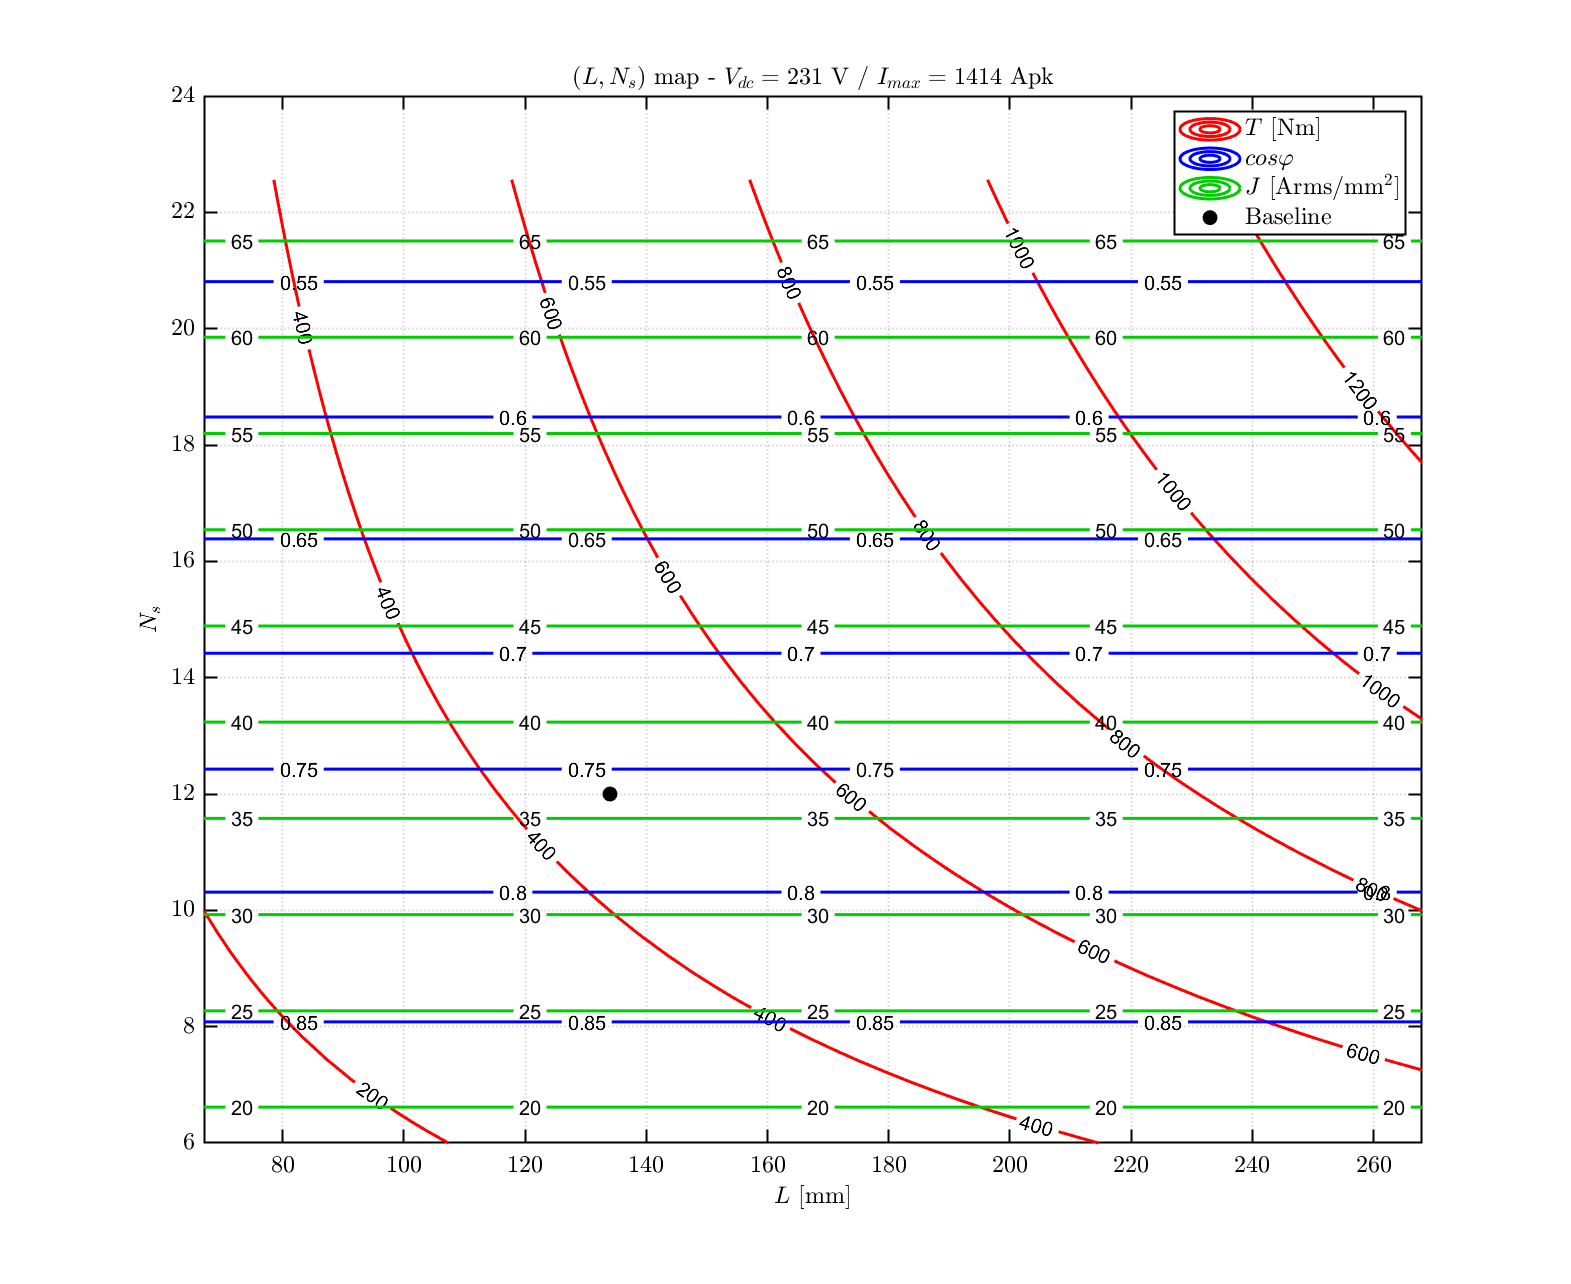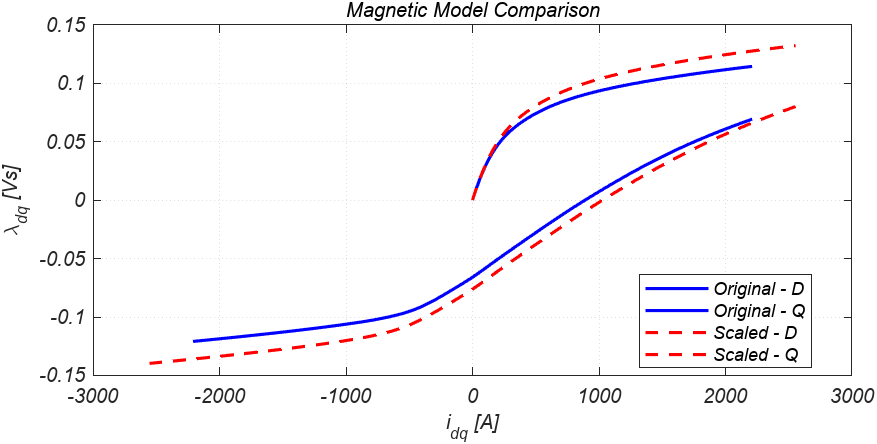

% load dq Map

% Model Scaling  
% Scale Map -> Scale Model 
% Scale Map : 

% Pareto Point From Scaled Model 


Scaled 된 Model의 TN은 비활성화 (Why?

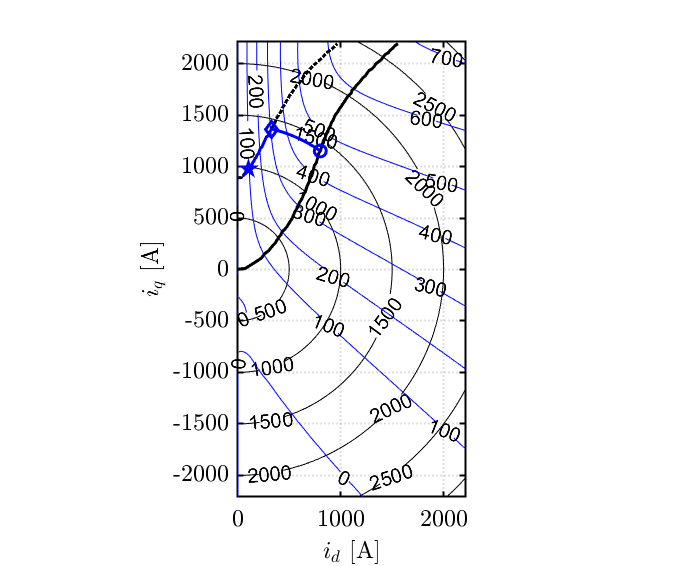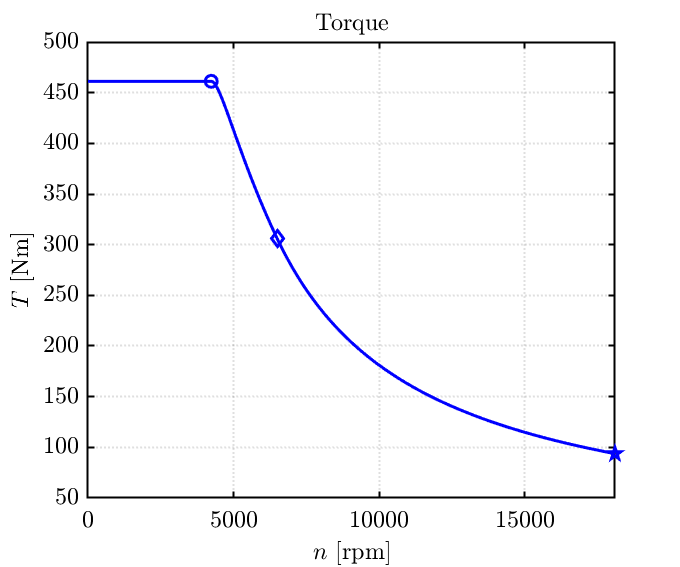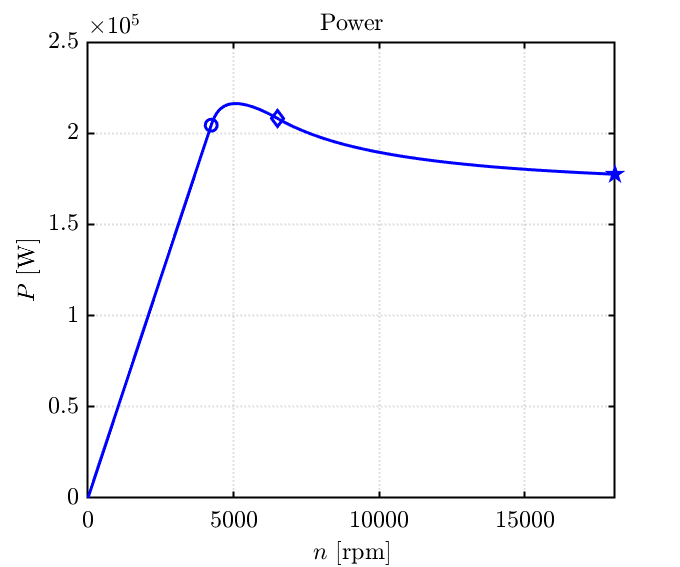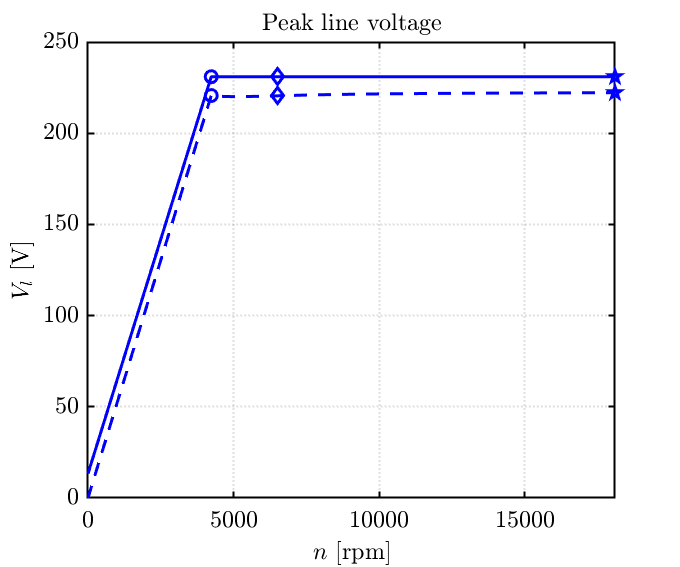

% MotorCAD로 export? 


## 온도 해석

방법들 나열

syre 

- Contant Thermal Kj 확인필요 -> 

- devTransientThermalRise.mlx 참고

devTransientThermalrise4Scaling


## 최적화 - 전압방정식은 제약조건, 효율최대, 원하는 토크와 오차가 최소가 되는 id,iq값찾기

사용법

% Define the objective function to maximize efficiency
objective = @(x) -Efficiency(x);

% Define the nonlinear constraint function for voltage equation
nonlcon = @(x) VoltageEquation(x);

% Initial guess for id and iq
x0 = [0.5, 0.5];

% Define lower and upper bounds for id and iq
lb = [-1, -1];
ub = [1, 1];

% Solve the optimization problem using fmincon
options = optimoptions('fmincon', 'Algorithm', 'sqp');
[x_opt, fval] = fmincon(objective, x0, [], [], [], [], lb, ub, nonlcon, options);

% Display the optimized id and iq values
disp(['Optimized id: ', num2str(x_opt(1))]);
disp(['Optimized iq: ', num2str(x_opt(2))]);
disp(['Maximum Efficiency: ', num2str(-fval)]);


function efficiency = Efficiency(x)
    % Define your efficiency calculation here based on id and iq
    % For example: efficiency = some_function(x(1), x(2));
end

function voltage_eq = VoltageEquation(x)
    % Define the voltage equation as a constraint
    % For example: voltage_eq = some_equation(x(1), x(2)) - V_ref;
end


## 논문 작성용 데이터

- SPlaid 사이즈

- HDEV 사이즈 (참고논문 or 내 데이터) 외경 적층 아마도 동일할거임

손실, 토크 비교

-> 방열면적에 대하여, 온도에 대하여